# Chapter 06: Regression and Regularization

close all; clear all;
warning('off','all');

For visualization purposes, the datapoints $x^{(1)},\dots,x^{(m)}$ are unidimensional here. The hypothesis class is made of univariate polynomials of the form $h_c(x) = \sum_{j=0}^{deg}c_jx^j$, so the empirical risk becomes 

$\frac{1}{m}\sum_{i=1}^{m} (h_c(x^{(i)})-y_i)^2 = \frac{1}{m}\|X c-y\|_2^2$,

where $X$ is the $m\times(deg+1)$matrix with entries

$X_{i,j}=\left( x^{(i)} \right)^j, \quad i=1,\dots,m, \quad j=0,\dots,deg$.

Below, one works in the overparametrized regime where $deg+1>m$.

% generate the data
rng(36)                                  % comment out this line to generate a different dataset
m = 15;
x = [-1;sort(2*rand(m-2,1)-1);1];
y = x.^3 - 4*x.^2 + x + randn(m,1);

## Plain least squares leads to overfitting

% The least squares solution is obtained directly via polyfit
deg = 18;
c_least = polyfit(x,y,deg);

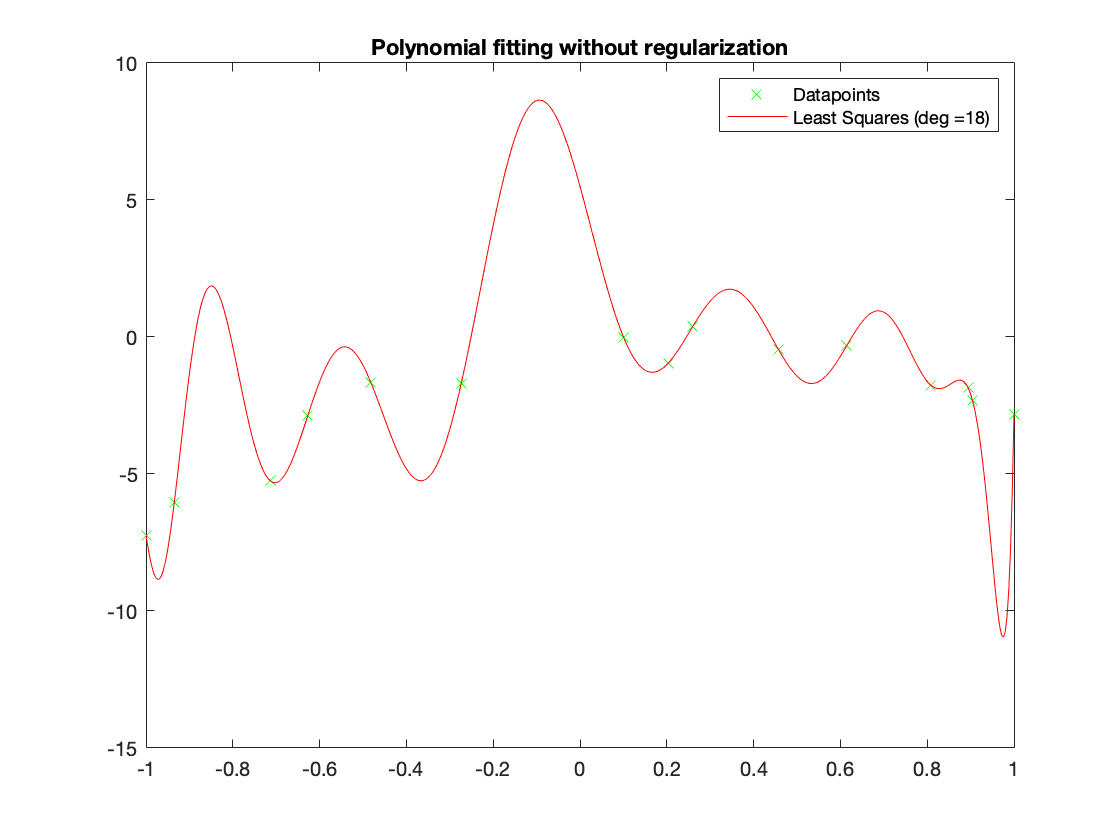

% visualize the least squares predictor
grid = linspace(-1,1,500);
figure(1)
plot(x,y,'gx',grid,polyval(c_least,grid),'r-');
legend('Datapoints',strcat('Least Squares (deg =',num2str(deg),')'));
title('Polynomial fitting without regularization')

## Using a Tikhonov regularization prevents overfitting

% construct the matrix X
X = zeros(m,deg+1);
for j=0:deg
    X(:,j+1) = x.^j;
end
% define and solve the appropriate linear system
lambda = 0.1;
A = X'*X+lambda^2*eye(deg+1);
c_tikho = linsolve(A,X'*y);

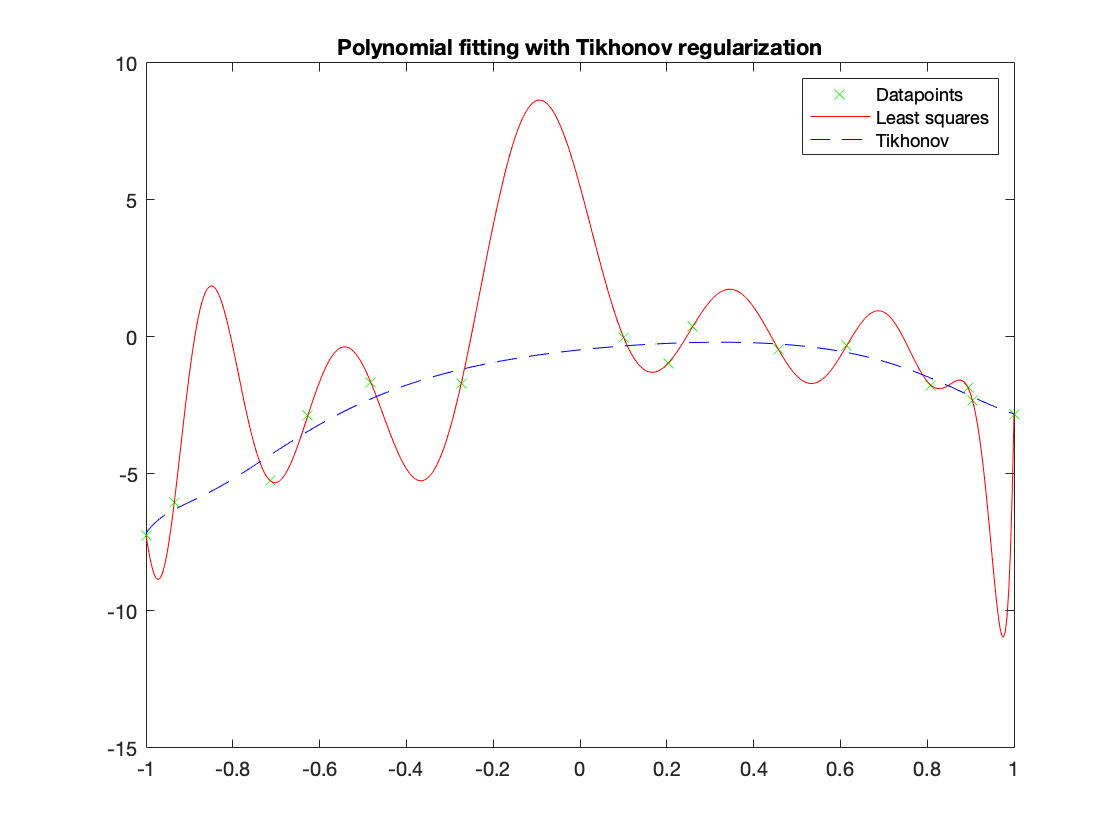

% visualize the Tikhonov predictor
plot(x,y,'gx',grid,polyval(c_least,grid),'r-',grid,polyval(flip(c_tikho),grid),'b--');
legend('Datapoints','Least squares','Tikhonov');
title('Polynomial fitting with Tikhonov regularization')

## Using a squared-LASSO regularization also prevents overfitting

X_aux = [X,-X;lambda*ones(1,2*deg+2)];
y_aux = [y;0];
cvx_quiet true
cvx_begin
variable c(2*deg+2) nonnegative
minimize norm(X_aux*c-y_aux)
cvx_end
c_lasso = c(1:deg+1)-c(deg+2:end);

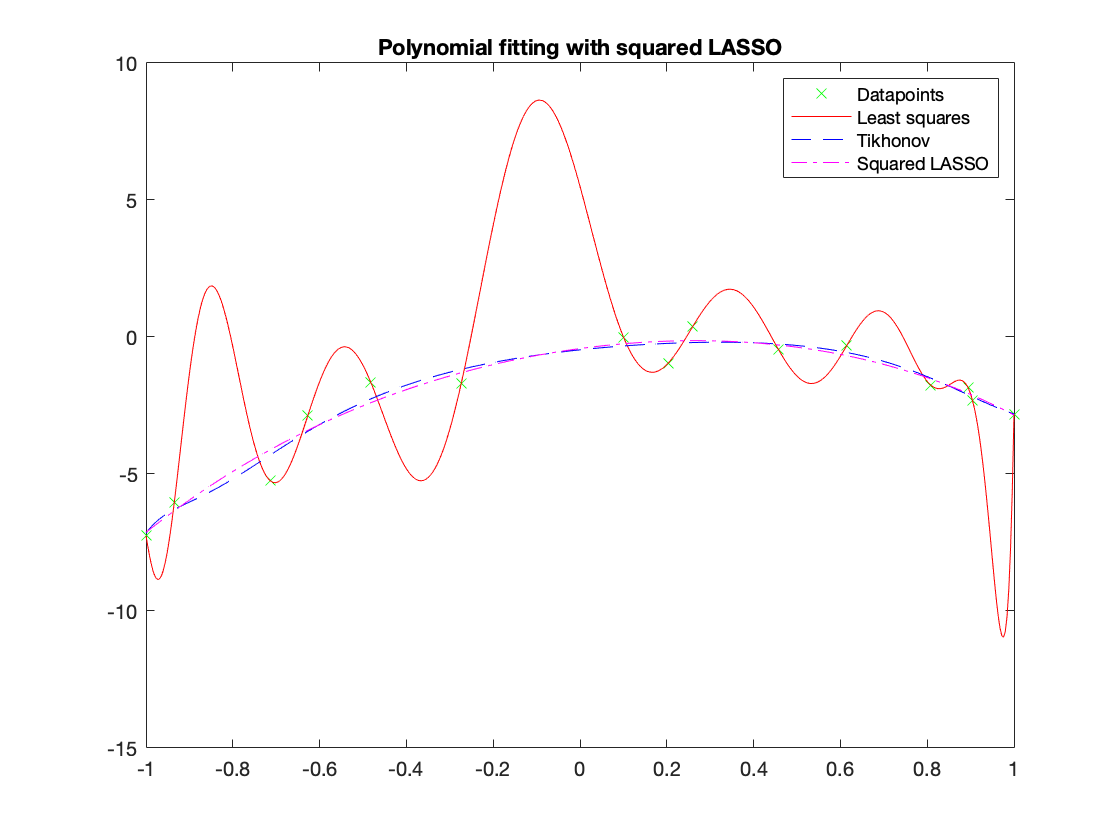

plot(x,y,'gx',grid,polyval(c_least,grid),'r-',grid,polyval(flip(c_tikho),grid),'b--',grid,polyval(flip(c_lasso),grid),'m-.');
legend('Datapoints','Least squares','Tikhonov','Squared LASSO');
title('Polynomial fitting with squared LASSO')

% Check the sparsity of the coefficient vector
fprintf('The number of non-zero coefficient is %i\n',sum(abs(c_lasso)>1e-5))

The number of non-zero coefficient is 5
